# Friction Model Response to Base Dynamics

clearvars
clc
close all

## Initialize Values

Jog = 80e-6; % Inertia [Nm2]

tFinal = 1;
tMaxStep = 0.0005;

doSim = 0;

if doSim
    open('SingleAxisGimbal_SIMPLE.slx')
end

## Populate Input vectors

PdegMin = 10;
PdegMax = 350;
PdegStep = 10;

PfreqMin = 0;
Pfreqmax = 10;
PfreqStep = 0.5;

PdegVec = (PdegMin:PdegStep:PdegMax)';
PfreqVec = (PfreqMin:PfreqStep:Pfreqmax)';

[X, f] = meshgrid(PdegVec, PfreqVec);
Xs = X(:);
fs = f(:);
Zs = zeros(length(Xs),1);

## Simulink Simulation

if doSim

    for i = 1 : length(Xs)
        Xi = Xs(i);
        fi = fs(i);
        sim('SingleAxisGimbal_SIMPLE.slx');
        Zs(i) = maxExtFricTorque.Data(:,1);
    end

    Z = reshape(Zs, size(X));
    
    contourf(X, f, Z*1000, '--' ,'ShowText', 'on')
    colorbar()
    title('External Torque [mNm]')
    xlabel('P - Amplitude [deg/s]');
    ylabel('P - frequency [hz]')
    set(gca, 'Fontsize', 12)
    
end

## Sanity Check


$$Q = Q_{ampl}\sin(2\pi\cdot Q_{frec}t) \\
\rightarrow |Q| = Q_{ampl} \\
\rightarrow |\dot{Q}| =  Q_{ampl} \cdot2 \pi Q_{frec}$$


% single point simulation
Xi = 60;
fi = 1;
if doSim
    sim('SingleAxisGimbal_SIMPLE.slx');
    T_ext_sim = maxExtFricTorque.Data(:,1)*1000;
    T_ext_anal = deg2rad(Xi)*(2*pi*fi)*Jog*1000;
    fprintf('Simulink: %.3f, Analythic: %.3f ----> error: %.1f [%%]', T_ext_sim, T_ext_anal,abs(T_ext_sim-T_ext_anal)/T_ext_anal*100);
    % ------------ Contour Plot -------------- %
    
end


## Analythical Calculation

Za = reshape(Jog .* deg2rad(Xs) .* (2*pi.*fs), size(X));
Za_mNm = Za*1000;

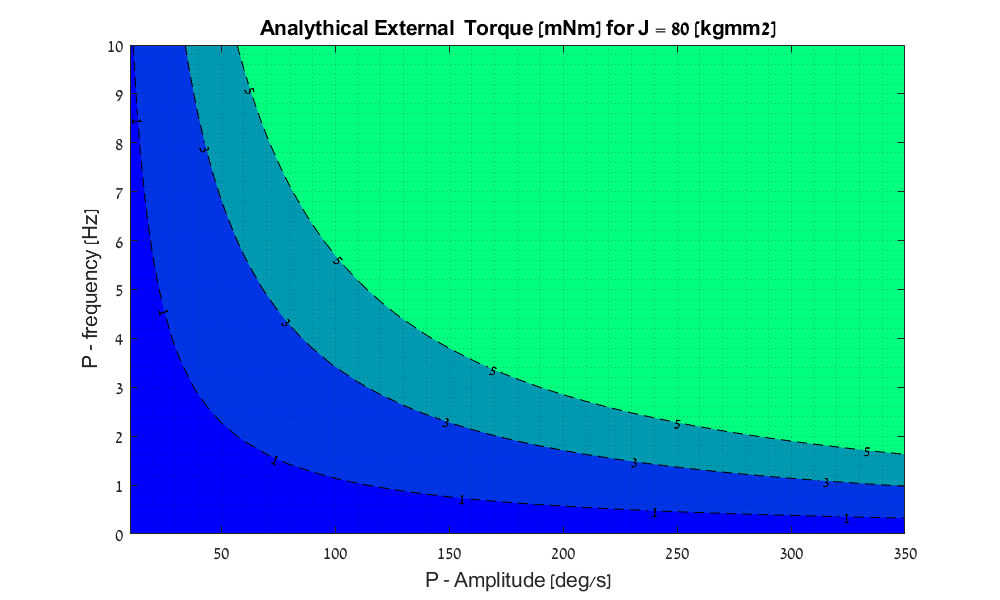

figure('Position',[0 0 1000 600])
[C,h] = contourf(X, f, Za_mNm ,[0 1 3 5] ,'ShowText', 'on', 'LineStyle','--');
clabel(C,h, 'Fontsize', 12, 'Color', 'black')
title(sprintf('Analythical External  Torque [mNm] for J = %d [kgmm2]', Jog*1e6))
xlabel('P - Amplitude [deg/s]');
ylabel('P - frequency [Hz]')
set(gca, 'Fontsize', 14)
colormap winter
grid minor